# Quantum Antibunching 1 Photon

Simulations for invited paper: C**omputational imaging with joint quantum and classical information**

#### First load data

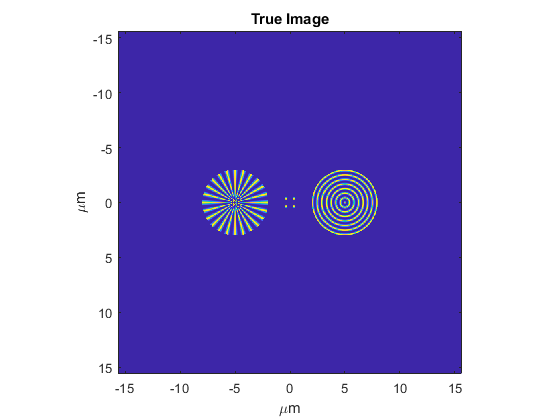

addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SPIFIandCHIRPTSims")
addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SDI\MPSFIFforSDI")
x=load('xspatvecXT.mat');
x=x.Expression1;
fx=load('xspatfreqXT.mat');
fx=fx.Expression1;
y=load('yspatvecXT.mat');
y=y.Expression1;
fy=load('yspatfreqXT.mat');
fy=fy.Expression1;
trueimage=load("trueimageXT.mat");
trueimage=trueimage.Expression1;
figure; imagesc(x,y,trueimage)
xlabel('\mum')
ylabel('\mum')
axis square
title('True Image')

Noise Free

%1
for jj=1:2
    s=load(strcat('imgNFXT1',num2str(jj),'.mat'));
    imgNFXT1(:,:,jj)=s.Expression1;
end 
%2
for jj=1:4
    s=load(strcat('imgNFXT2',num2str(jj),'.mat'));
    imgNFXT2(:,:,jj)=s.Expression1;
end 
%3
for jj=1:6
    s=load(strcat('imgNFXT3',num2str(jj),'.mat'));
    imgNFXT3(:,:,jj)=s.Expression1;
end 

Need to transform back into real space!!!

for jj=1:2
imgNFXT1(:,:,jj)=real(ifftshift(ifft2((ifftshift(imgNFXT1(:,:,jj))))));
end

for jj=1:4
imgNFXT2(:,:,jj)=real(ifftshift(ifft2((ifftshift(imgNFXT2(:,:,jj))))));
end
for jj=1:6
imgNFXT3(:,:,jj)=real(ifftshift(ifft2((ifftshift(imgNFXT3(:,:,jj))))));
end

With Noise

%1
for jj=1:2
    s=load(strcat('imgNoiseXT1',num2str(jj),'.mat'));
    imgNoiseXT1(:,:,jj)=s.Expression1;
end 
%2
for jj=1:4
    s=load(strcat('imgNoiseXT2',num2str(jj),'.mat'));
    imgNoiseXT2(:,:,jj)=s.Expression1;
end 
%3
for jj=1:6
    s=load(strcat('imgNoiseXT3',num2str(jj),'.mat'));
    imgNoiseXT3(:,:,jj)=s.Expression1;
end 

Load in OTFs

%1
for jj=1:2
    s=load(strcat('OTFXT1',num2str(jj),'.mat'));
    OTFXT1(:,:,jj)=s.Expression1;
end 
%2
for jj=1:4
    s=load(strcat('OTFXT2',num2str(jj),'.mat'));
    OTFXT2(:,:,jj)=s.Expression1;
end 
%3
for jj=1:6
    s=load(strcat('OTFXT3',num2str(jj),'.mat'));
    OTFXT3(:,:,jj)=s.Expression1;
end 

## Plots

figure;
t=tiledlayout(3,3)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 3]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


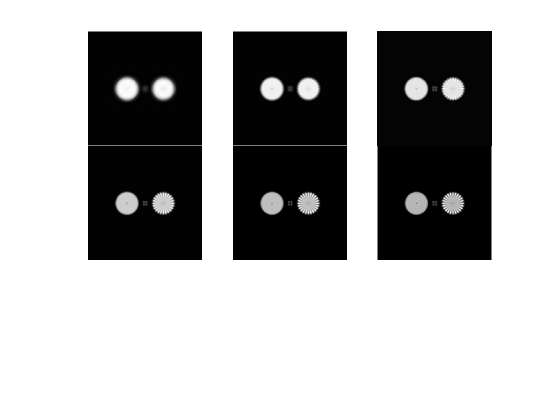

colormap gray
nexttile
imagesc(imgNFXT3(:,:,1))
axis square
axis off
nexttile
imagesc(imgNFXT3(:,:,2))
axis square
axis off
nexttile
imagesc(imgNFXT3(:,:,3))
axis square
axis off
nexttile
imagesc(imgNFXT3(:,:,4))
axis square
axis off
nexttile
imagesc(imgNFXT3(:,:,5))
axis square
axis off
nexttile
imagesc(imgNFXT3(:,:,6))
axis square
axis off
t.TileSpacing = 'none';


t=tiledlayout(2,2)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


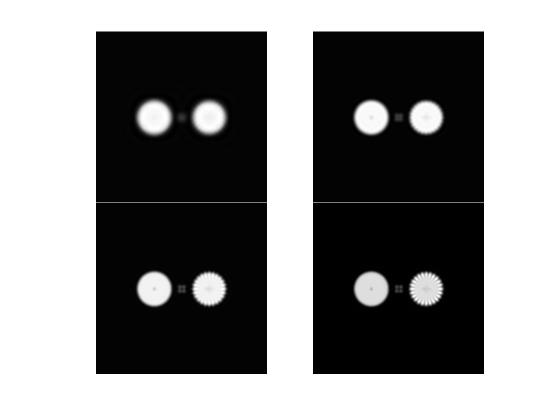

colormap gray
nexttile
imagesc(imgNFXT2(:,:,1))
axis square
axis off
nexttile
imagesc(imgNFXT2(:,:,2))
axis square
axis off
nexttile
imagesc(imgNFXT2(:,:,3))
axis square
axis off
nexttile
imagesc(imgNFXT2(:,:,4))
axis square
axis off

t.TileSpacing = 'none';

t=tiledlayout(1,2)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


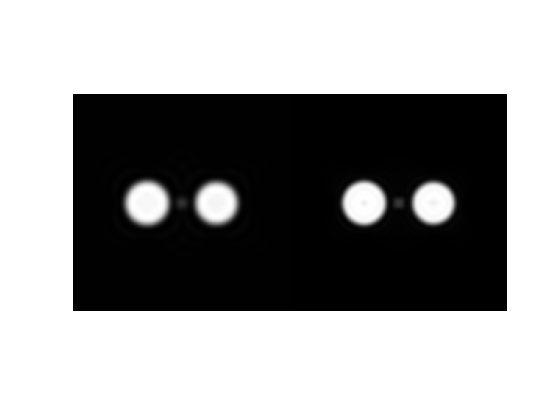

colormap gray
nexttile
imagesc(imgNFXT1(:,:,1))
axis square
axis off
nexttile
imagesc(imgNFXT1(:,:,2))
axis square
axis off


t.TileSpacing = 'none';

Images with noise

figure;
t=tiledlayout(2,3)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 3]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


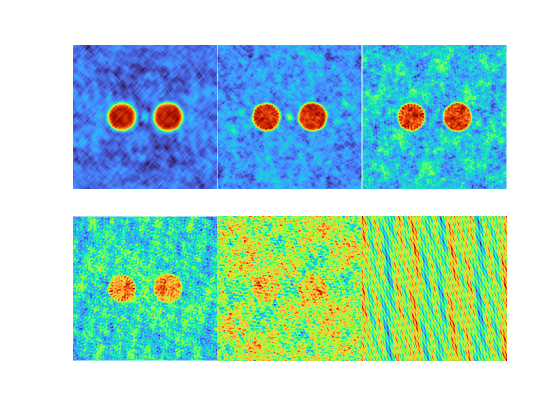

colormap Turbo
nexttile
imagesc(imgNoiseXT3(:,:,1))
axis square
axis off
nexttile
imagesc(imgNoiseXT3(:,:,2))
axis square
axis off
nexttile
imagesc(imgNoiseXT3(:,:,3))
axis square
axis off
nexttile
imagesc(imgNoiseXT3(:,:,4))
axis square
axis off
nexttile
imagesc(imgNoiseXT3(:,:,5))
axis square
axis off
nexttile
imagesc(imgNoiseXT3(:,:,6))
axis square
axis off
t.TileSpacing = 'none';

figure;
t=tiledlayout(2,2)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


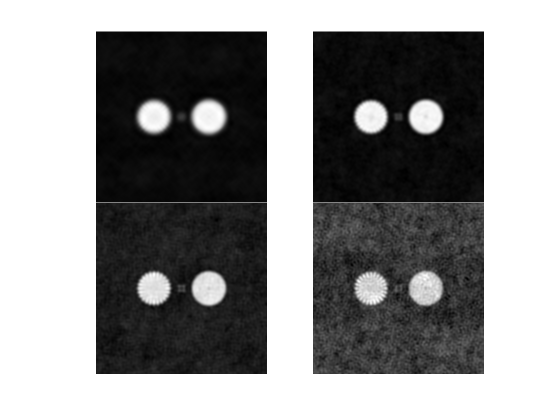

colormap gray
nexttile
imagesc(imgNoiseXT2(:,:,1))
axis square
axis off
nexttile
imagesc(imgNoiseXT2(:,:,2))
axis square
axis off
nexttile
imagesc(imgNoiseXT2(:,:,3))
axis square
axis off
nexttile
imagesc(imgNoiseXT2(:,:,4))
axis square
axis off

t.TileSpacing = 'none';

figure;
t=tiledlayout(1,2)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


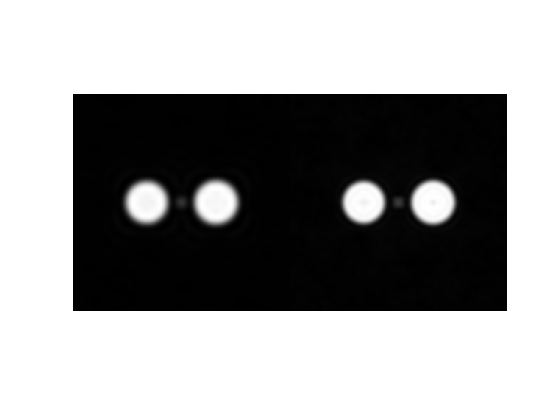

colormap gray
nexttile
imagesc(imgNoiseXT1(:,:,1))
axis square
axis off
nexttile
imagesc(imgNoiseXT1(:,:,2))
axis square
axis off


t.TileSpacing = 'none';

OTFs

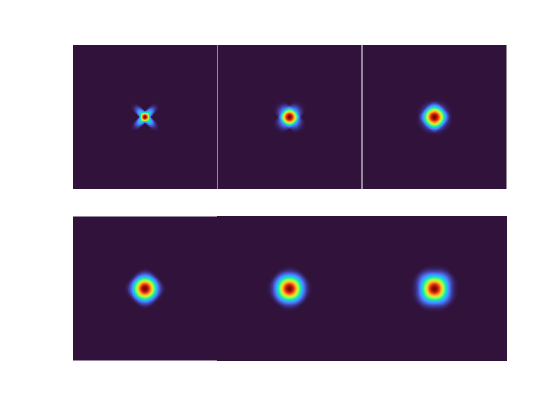

tiledlayout(2,3,'TileSpacing',"none");
colormap Turbo
nexttile
imagesc(OTFXT3(:,:,1))
axis square
axis off
nexttile
imagesc(OTFXT3(:,:,2))
axis square
axis off
nexttile
imagesc(OTFXT3(:,:,3))
axis square
axis off
nexttile
imagesc(OTFXT3(:,:,4))
axis square
axis off
nexttile
imagesc(OTFXT3(:,:,5))
axis square
axis off
nexttile
imagesc(OTFXT3(:,:,6))
axis square
axis off

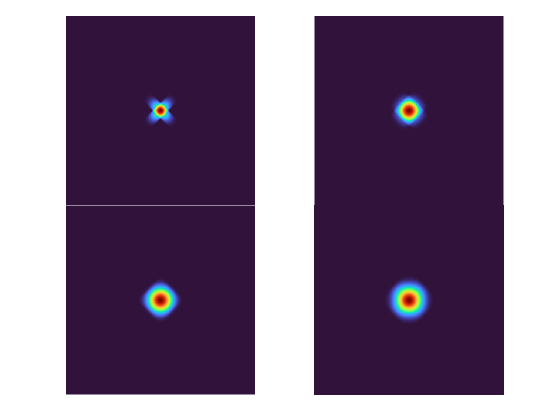

tiledlayout(2,2,'TileSpacing',"none",'Padding',"compact");
colormap Turbo
nexttile
imagesc(OTFXT2(:,:,1))
axis square
axis off
nexttile
imagesc(OTFXT2(:,:,2))
axis square
axis off
nexttile
imagesc(OTFXT2(:,:,3))
axis square
axis off
nexttile
imagesc(OTFXT2(:,:,4))
axis square
axis off

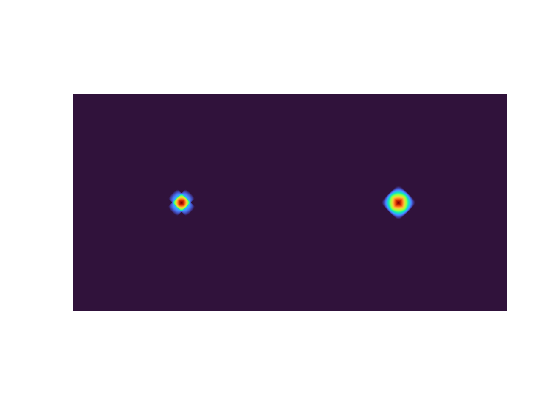

tiledlayout(1,2,'TileSpacing',"none",'Padding',"tight");
colormap Turbo
nexttile
imagesc(OTFXT1(:,:,1))
axis square
axis off
nexttile
imagesc(OTFXT1(:,:,2))
axis square
axis off

Generate PSFs

for ii=1:6
    PSFXT3(:,:,ii)=abs(ifftshift(ifft2(ifftshift(OTFXT3(:,:,ii)))));
end
for ii=1:6
    PSFXT3N(:,:,ii)=Norm(PSFXT3(:,:,ii));
end

for ii=1:4
    PSFXT2(:,:,ii)=abs(ifftshift(ifft2(ifftshift(OTFXT2(:,:,ii)))));
end
for ii=1:4
    PSFXT2N(:,:,ii)=Norm(PSFXT2(:,:,ii));
end

for ii=1:2
    PSFXT1(:,:,ii)=abs(ifftshift(ifft2(ifftshift(OTFXT1(:,:,ii)))));
end
for ii=1:2
    PSFXT1N(:,:,ii)=Norm(PSFXT1(:,:,ii));
end

s=size(PSFXT3N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSFXT3N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgNFXT3,[s(1) s(1)*s(3)]);
%bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=4000;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 5546.590671 seconds.


clear recMPIMNXT3 errorrecrecMPIMNXT3
recMPIMNXT3=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 4.4885e-06

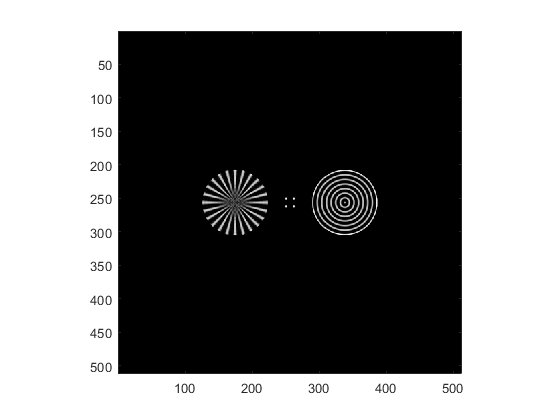

for ii=1:size(recMPIMNXT3,3)
    errorrecrecMPIMNXT3(ii)=immse(Norm(trueimage),Norm(recMPIMNXT3(:,:,ii)));
end

[eval locm]=min(errorrecrecMPIMNXT3);
figure; imagesc(recMPIMNXT3(:,:,locm)) %locm=4000
axis square
colormap gray

Bestim=recMPIMNXT3(:,:,locm);
save('imgNFXT3ReconNoNoise.mat','Bestim','-v7.3','-nocompression');

% XT3 with noise

PSFS=PSFXT2N(:,:,1:4);
Images=imgNoiseXT2(:,:,1:4);

s=size(PSFS);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSFS,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(Images,[s(1) s(1)*s(3)]);
%bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
bdn=conv_fft2(Imdata,delta);
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=500;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 422.003540 seconds.


clear recMPIMN3XT errorrecrecMPIMN3XT
recMPIMN3XT=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0445

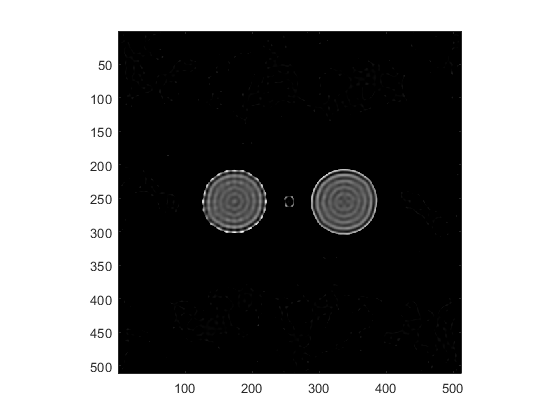

for ii=1:size(recMPIMN3XT,3)
    errorrecrecMPIMN3XT(ii)=immse(Norm(trueimage),Norm(recMPIMN3XT(:,:,ii)));
end

[evalXT locmXT]=min(errorrecrecMPIMN3XT);
figure; imagesc(recMPIMN3XT(:,:,locmXT))
axis square
colormap gray

% XT2 with noise

PSFS=PSFXT2N;
Images=imgNoiseXT2;

s=size(PSFS);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSFS,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(Images,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(Imdata,delta);
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=500;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 433.120523 seconds.


clear recMPIMN3XT errorrecrecMPIMN3XT
recMPIMN3XT=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0445

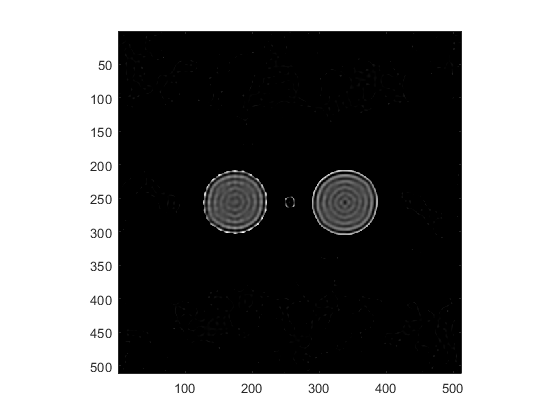

for ii=1:size(recMPIMN3XT,3)
    errorrecrecMPIMN3XT(ii)=immse(Norm(trueimage),Norm(recMPIMN3XT(:,:,ii)));
end

[evalXT locmXT]=min(errorrecrecMPIMN3XT);
figure; imagesc(recMPIMN3XT(:,:,locmXT))
axis square
colormap gray

% XT2 noise free

PSFS=PSFXT2N;
Images=imgNFXT2;

s=size(PSFS);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSFS,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(Images,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(Imdata,delta);
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=1000;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 881.460975 seconds.


clear recMPIMN3XT errorrecrecMPIMN3XT
recMPIMN3XT=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0357

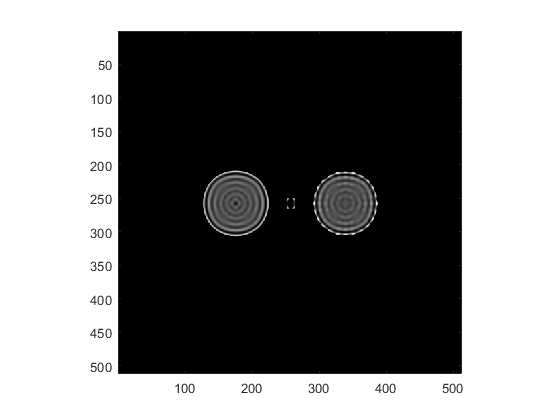

for ii=1:size(recMPIMN3XT,3)
    errorrecrecMPIMN3XT(ii)=immse(Norm(trueimage),Norm(recMPIMN3XT(:,:,ii)));
end

[evalXT locmXT]=min(errorrecrecMPIMN3XT);
locmXT
figure; imagesc(recMPIMN3XT(:,:,locmXT))
axis square
colormap gray